# Data Extraction

% Get the relevant data again

dirBurnFlags = ['/Users/lukemartin/Library/CloudStorage/OneDrive-McGillUniversity/' ...
    'Undergrad/Lab Work/2026 Summer Research/Data/8 Minute CSVs/Burnside/Burnside Flags.csv'];

dirGaultFlags = ['/Users/lukemartin/Library/CloudStorage/OneDrive-McGillUniversity/' ...
    'Undergrad/Lab Work/2026 Summer Research/Data/8 Minute CSVs/Gault/Gault Flags.csv'];

% Extract the variables - Burn
dataBurn = readmatrix(dirBurnFlags);
dateTimeBurn = nonzeros(dataBurn(1, :));
flagsBurn = dataBurn(2, 1 : length(dateTimeBurn));

% Extract the variables - Gault
dataGault = readmatrix(dirGaultFlags);
dateTimeGault = nonzeros(dataGault(1, :));
flagsGault = dataGault(2, 1:length(dateTimeGault));

% Use datetime conversion from 8_Minute_Averages script
MJDConversion = 51544;
timeBurn = datetime(dateTimeBurn + MJDConversion, 'ConvertFrom', 'modifiedjuliandate');
timeGault = datetime(dateTimeGault + MJDConversion, 'ConvertFrom', 'modifiedjuliandate'); 

# Combined Comparison Graph

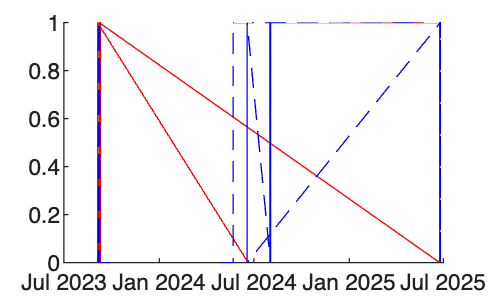

% Plot a combined figure
figure 
hold on
plot(timeBurn, flagsBurn,'-', color='r')
plot(timeGault, flagsGault, '--', color='b')
hold off

I think that this is right, but it's hard to tell with such an incomplete time series... eventually this will be a useful figure, however